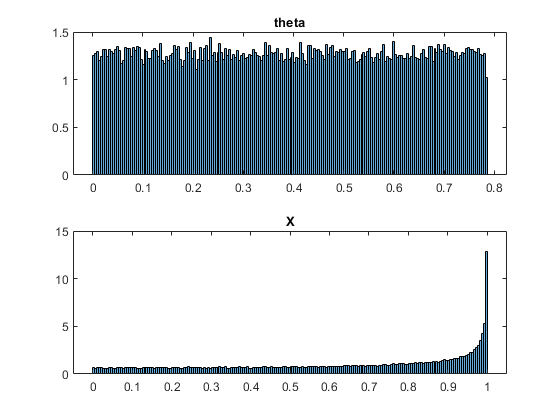

theta = pi/4 * rand(1,1e5);
x = sin(2*theta);

figure
subplot(2,1,1)
histogram(theta, 200,"Normalization","pdf")
title('theta')

subplot(2,1,2)
histogram(x, 200, 'Normalization',"pdf")
title('X')


mu_X = mean(x)

mu_X = 0.6365

std_X = std(x)

std_X = 0.3082

med_X = median(x)

med_X = 0.7076

syms r
v = (1/2)^(1/4)

v = 0.8409

res = int((v-r)*4*r^3, 0, v) + int((r-v)*4*r^3, v, 1)

$$res = \frac{589533967453401134815544199261593697960076434596100482348341155477667160620727}{4631683569492647816942839400347516314130799386625622561578303360316525185597440}$$

eval(res)

ans = 0.1273

syms p q e
e = 1-p-q

$$e = 1-q-p$$

eqn = p+q+4*e - (p-q-2*e)^2

$$eqn = 4-3\,q-{\left(3\,p+q-2\right)}^{2}-3\,p$$

expand(eqn)

$$ans = -9\,p^{2}-6\,p\,q+9\,p-q^{2}+q$$

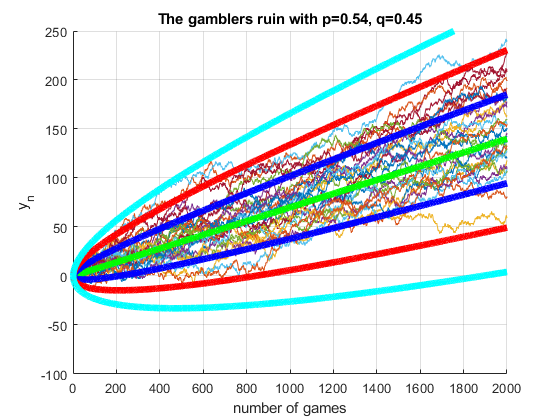

p = 0.54;
q = 0.45;
e = 0.01;
t=(0:2000);
u=t*(p-q-2*e);
s=sqrt(t*(4*p*q + 9*p*e + q*e));
figure
hold on
for j = 1:30
    r = rand(1,2000);
    y = zeros(size(t));
    for k=1:2000
        if r(k)<p
            y(k+1) = y(k)+1;
        elseif r(k)>(1-e)
            y(k+1) = y(k)-2;
        else
            y(k+1) = y(k)-1;
        end
    end
    plot(t,y);
end

plot(t,u,'g',"LineWidth",5);hold on;
plot(u-s,'b',"LineWidth",5);plot(u+s,'b',"LineWidth",5);
plot(u-2*s,'r',"LineWidth",5);plot(u+2*s,'r', "LineWidth",5)
plot(u-3*s,'c',"LineWidth",5);plot(u+3*s,'c',"LineWidth",5);grid; axis([0,2000,-100,250])

xlabel('number of games');ylabel('y_n');
title('The gamblers ruin with p=0.54, q=0.45')